# Jeff Suitor - 400138679 - A4 - 4QZ3

clc; clear; close all
data = load("dataA4.mat").mridata2;

figure(1)
hold on
plot(squeeze(data(10,10,:)))
title("10, 10 pixel change over scans")
xlabel("Scans")
ylabel("Pixel value")
hold off

Select the pixel located at the 10,10 position and plot to see how it changes with respect to each scan.

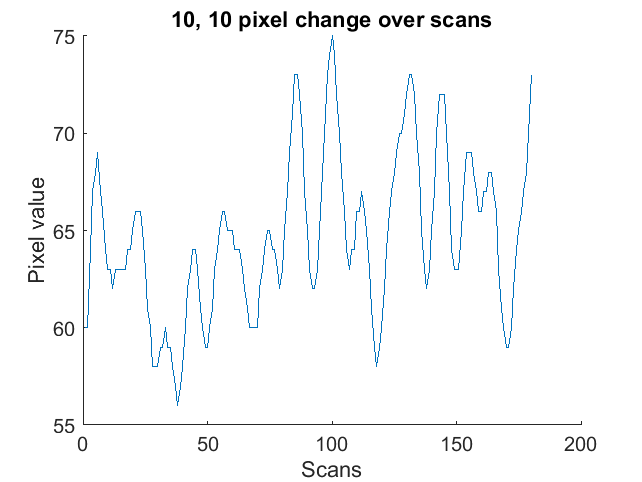

figure(2)
hold on
imshow(data(:,:,90), [])
truesize([640 640])

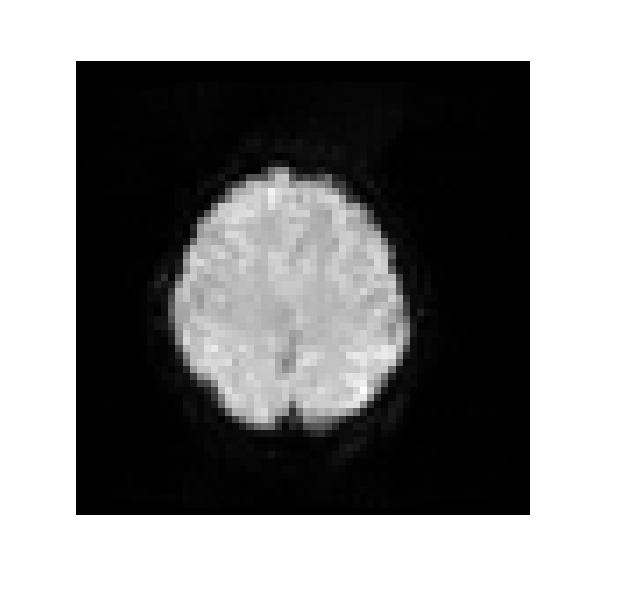

hold off

Plot the grayscale image of the 90th brain scan. There are areas of high signal located in the brain although based purely on the image it is difficult to determine the structure. There appears to be some motion artifacting around the outside of the image as seen by the haloing. 

n = 180;
Fs = 0.5;

f = (0:n/2 -1) * Fs/n;

TR = 1/Fs;

t = (0:(n-1)) * TR;

samp_hz = 1/60;

idealSig = (square(2 * pi * samp_hz * t) + 1) / 2;
idealSig2 = square(2 * pi * samp_hz * t);
XwithDC = abs(fft(idealSig));
XnoDC = abs(fft(idealSig2));

Create the necessary signals. There are 180 scans (n) with a scan every 2 seconds (TR) and a frequency of 0.5Hz (Fs). The period is 60s so the sampling Hz is 1/60 (samp_hz). Generate the ideal signal with and without DC using the square function. Take the magnitude of both of these ffts.

## Part A: Correlation Analysis

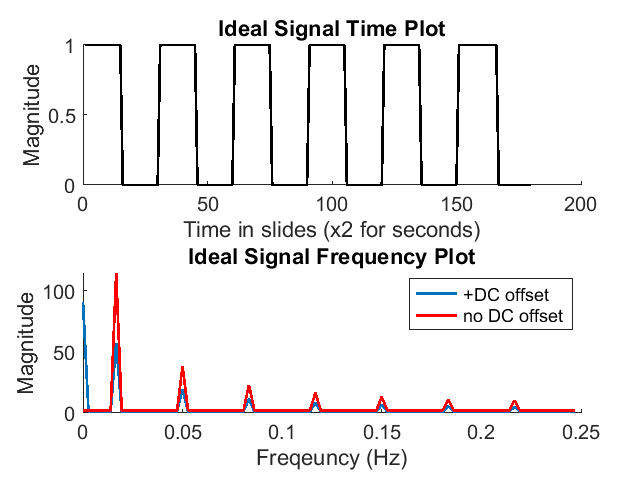

figure(3)
title("Fourier Analysis of Ideal Signal")
subplot(2, 1, 1)
hold on
plot(1:n, idealSig, 'k', 'linewidth', 2)
xlabel("Time in slides (x2 for seconds)")
ylabel("Magnitude")
title("Ideal Signal Time Plot")
hold off

subplot(2, 1, 2)
hold on
plot(f, XwithDC(1:n/2), 'linewidth', 2)
plot(f, XnoDC(1:n/2), '-r', 'linewidth', 2)
title("Power spectral density")
xlabel("Freqeuncy (Hz)")
title("Ideal Signal Frequency Plot")
legend("+DC offset", "no DC offset")
ylabel("Magnitude")
hold off

Every 15 scans (15 scans x 2 scans/seconds  = 30 seconds) the block was toggled either on or off. This can be seen in the first figure in the subplot. In the second figure of the subplot the ideal magnitude of the fft is plotted both with and without the DC signal. Due to the square wave being a repeating waveform, it can be represented as a series of sine waves that are multiples of one and other, also known as harmonics. These harmonics when plotted at their different frequencies will have reduced magnitude at each subsequence frequency as their contribution to the construction of the square wave is less.

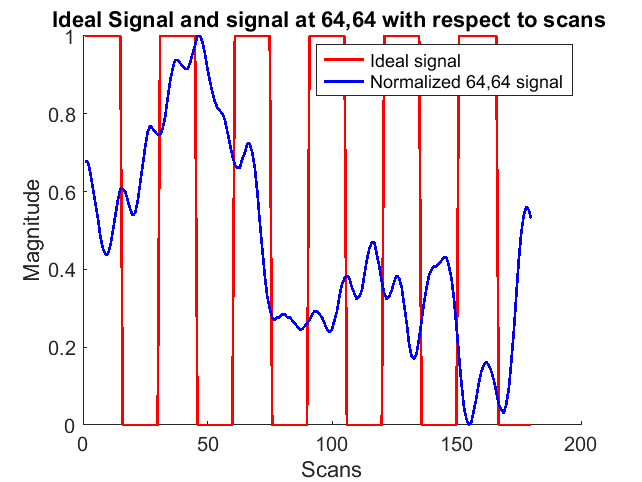

COR = zeros(64,64);
CORp = zeros(64,64);
for y=1:64
    for x=1:64
        if mean(data(y,x,:)) < 1000
            COR(y,x) = 0;
            CORp(y, x) = 1;
        else
            qq = mat2gray(squeeze(data(y,x,:)));
            [r,p] = corrcoef(idealSig, qq');
            COR(y,x) = r(1,2);
            CORp(y,x) = p(1,2);
        end
    end
end
figure(4)
hold on
plot(idealSig, '-r', 'linewidth', 2)
plot(qq, 'b', 'linewidth', 2)
title("Ideal Signal and signal at 64,64 with respect to scans ")
xlabel("Scans")
ylabel("Magnitude")
legend("Ideal signal", "Normalized 64,64 signal")
hold off

Plotting the ideal signal against the normalized signal at the 64,64 pixel with respect to scans shows some potential correlation but it is hard to determine the degree of correlation. The mat2gray function normalizes between 0 and 1 (the example from tutorial only scaled the max to 1 but failed to set the minimum to 0) setting the minimum value as 0 and the maximum value as 1. In the for loop corrcoef was also run to determine the degree of correlation. 1000 was used as the cutoff value as it appeared to remove unintended background noise, which was identified by viewing the image output below. Below 1000, there were extraneous regions which did not represent the brain which could be seen. Beyond 1000 there appeared to be loss of significant data as the boundaries of the brain shrank in size which would result in significant signal being lost.

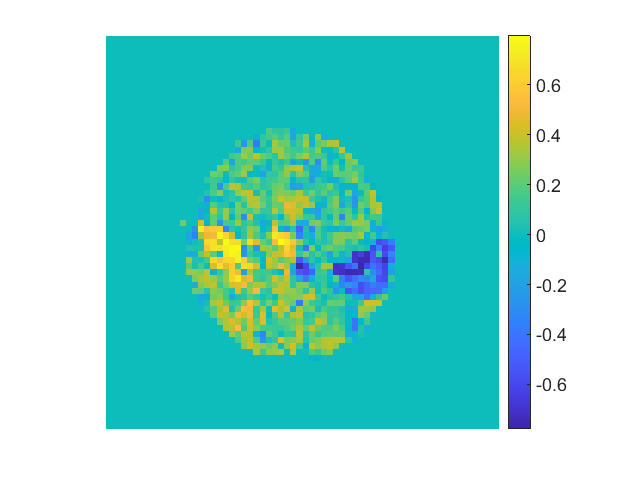

figure(5)
title("Correlation analysis of fMRI data")
imagesc(COR)
axis("image")
colorbar
axis off

The correlation image shown above shows 4 primary zones of strong correlation. The bright yellow zone on the left hand size and the small zone in the center show a high degree of rellation when the block is activted. The blue zone in the center and on the right side of the image show a strong degree of negative correlation indicating that when the block was deactivated, the signal in these zones increased and when the block was activated, the signal in these zones is reduced.

## Part B: Fourier Analysis

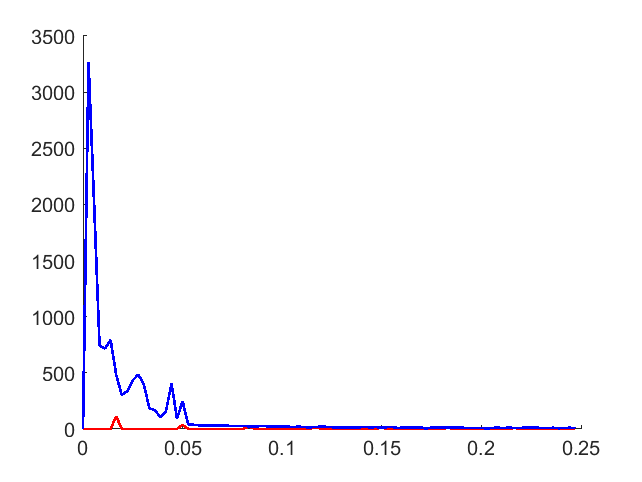

c = zeros(64,64);
cp = zeros(64,64);
for y=1:64
    for x=1:64
        if (mean(mean(data(y,x,:)))) < 1000
            c(y,x) = 0;
            cp(y, x) = 1;
        else
            pixFT = abs(fft(data(y,x,:) - mean(data(y,x,:))));
            [c(y,x), cp(y,x)] = corr(squeeze(pixFT), squeeze(XnoDC)');
        end
    end
end

figure(6)
hold on
plot(f, XnoDC(1:180/2), '-r', 'linewidth', 2)
plot(f, squeeze(pixFT(1:180/2)), '-b', 'linewidth', 2)
hold off

Plotting the half spectrum of the ideal signal with no dc and the half spectrum of the fourier transofmred centered around the mean indicates likely some correlation between the high frequency signals but is difficult to determine the degree of correlation with the low frequency signals. A cut off of 1000 was once again used to remove extra noise without too much loss of signal.

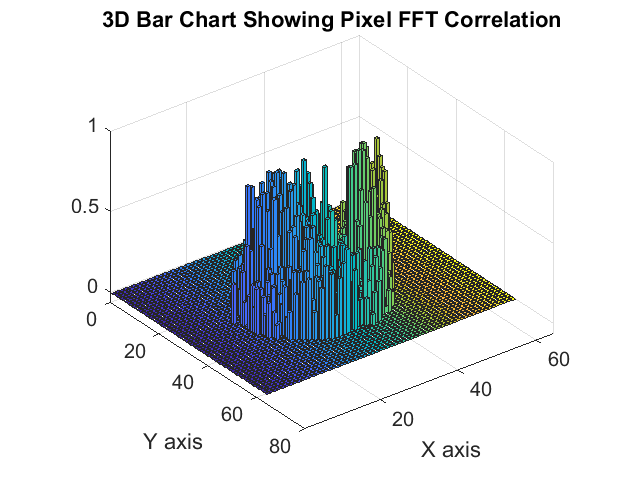

figure(7)
bar3(c)
title("3D Bar Chart Showing Pixel FFT Correlation")
xlabel("X axis")
ylabel("Y axis")

Plotting all the correlation coefficients as a 3d bar graph it can be seen that correlation only exists in the area representing the brain. The zones of high correltaion can be seen on left side and right side of the brain, opposite on and other along with some ones of high signal located near the center of the brain..

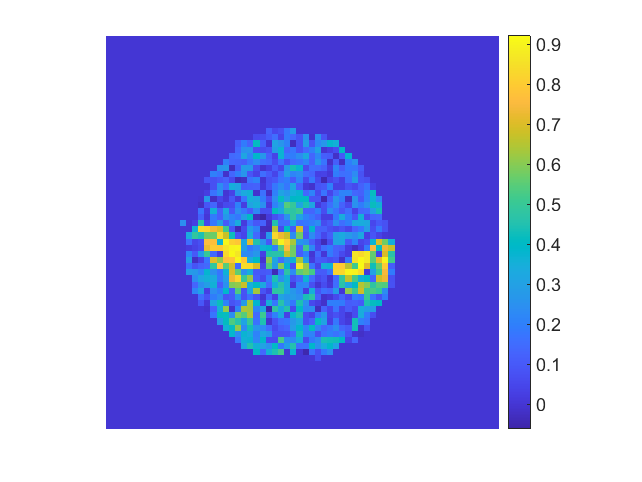

figure(8)
title("Fourier analysis of data")
imagesc(c)
axis('image')
axis off
colorbar

By plotting the correlation as an image a top view of the bar chart can be taken which once again shows these areas of high correlation  as the yellow zones in the above image. The zones in the center appear as the light green regions.

## Part C: PCA Analysis

data_2d = reshape(data, 64*64, 180);
[coeff, score, latent, ~, explained] = pca(data_2d);

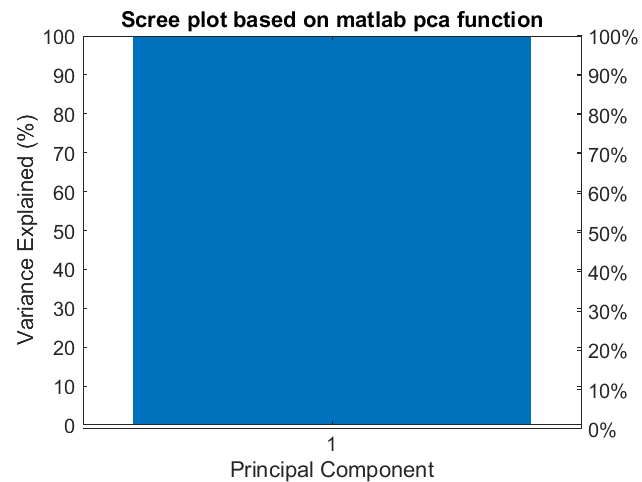

pca1 = reshape(score(:,1), 64, 64);
pca2 = reshape(score(:,2), 64, 64);
pca3 = reshape(score(:,3), 64, 64);
pca4 = reshape(score(:,4), 64, 64);
pca5 = reshape(score(:,5), 64, 64);

figure(9)
pareto(explained)
xlabel('Principal Component')
ylabel('Variance Explained (%)')
title("Scree plot based on matlab pca function")

According to the matlab PCA function, the first principal component is able to explain over 99% of the variance.

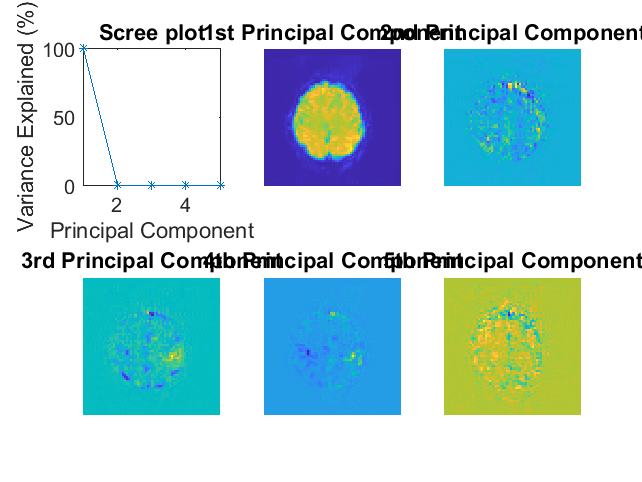


figure(10)
subplot(2,3,1)
plot(mat2gray(latent(1:5)) * 100, '-*');
title('Scree plot')
axis('square')
ylabel("Variance Explained (%)")
xlabel("Principal Component")
xlim([1 5])

subplot(2,3,2)
imagesc(pca1)
title("1st Principal Component")
axis off
axis("image")

subplot(2,3,3)
imagesc(pca2)
title("2nd Principal Component")
axis off
axis("image")

subplot(2,3,4)
imagesc(pca3)
title("3rd Principal Component")
axis off
axis("image")

subplot(2,3,5)
imagesc(pca4)
title("4th Principal Component")
axis off
axis("image")

subplot(2,3,6)
imagesc(pca5)
title("5th Principal Component")
axis off
axis("image")

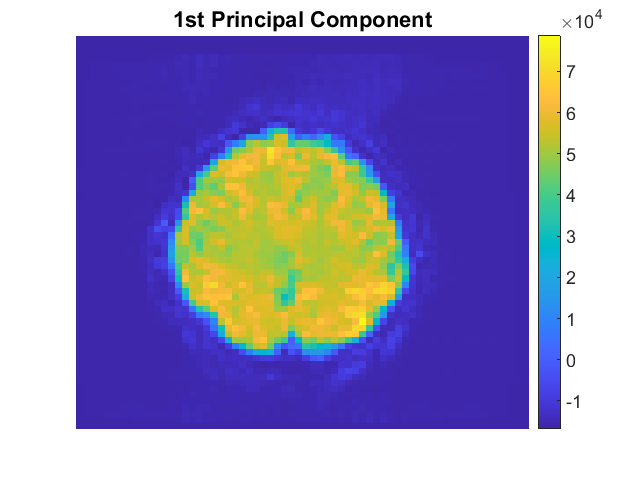


figure(11)
imagesc(pca1)
axis off
colorbar
title("1st Principal Component")

By normalizing the latent values between 0 and 1 and then multiplying by 100 the scree plot shows the variance percent explained by each principal component. This scree plot agrees with the ouput of the matlab pca function indicating that the signal is almost entirely composed of PCA 1. The first principal component shows a high degree of signal located within the brain as  expected. Therefore, based on the high percentage variance explained by the first principal component the other components can be deemed insignificant. Although interestingly, the second most important principal component outlines the exterior of the brain, similar to how motion artifacting would outline an MRI image, as the slight motion causes distortions in the scan. From my previous experiencing working with MRI I know that MRI is sensitive to motion which would explain how the second highest principal component could be due to motion artifacting. Another indicator that this may be motion artifacting is that the signal extends beyond the regions defined by the range simiilar to how the haloing seen in MRI images due to motion artifacts.While PCA 3, 4, 5 do show brain like strucutres their contribution to signal is so small that there is likely limited significance. Although, PCA3 does still feature the same features and reversed directionality compared to the correlation analysis indicating that there may some correlation. However, there are also multiple regions in PCA 3 not found in the correlation analysis which could be significant but due to the small contribution is likely just noise. PCA 1 also features signal outside the brain represntative of noise, likely due again to motion artifacting which could be filtered to better improve the image.

## Part D: PCA, Fourier, And Correlation Analysis

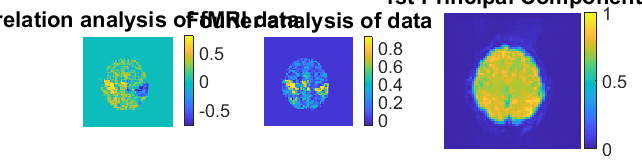

figure(12)
subplot(1,3,1)
imagesc(COR)
title("Correlation analysis of fMRI data")
axis("image")
colorbar
axis off

subplot(1,3,2)
imagesc(c)
title("Fourier analysis of data")
axis('image')
axis off
colorbar

subplot(1,3,3)
imagesc(mat2gray(pca1))
axis off
colorbar
title("1st Principal Component")
truesize([192 192])

The 3 forms of analysis show different results but with some degree of similarity. Firstly, the PCA analysis showed that there is only 1 principal component that makes up almost all the variance. This means that all other principal components can be ignored due to their minimal contributions. When comparing the images side by side it is diffcult to recognize any similarity between PCA and the other two forms of analysis other than still having a shape matching the brain.

The fourier and correlation analysis however, both show regions on the left hand and right hand side of the brain that match indicating areas of signal change based on activation changes. The fourier analysis doesn't show the directionality while the correlation analysis shows that the area on the left side of the image activates when the block is activated whereas the area on the right hand side of the image actiaves when the block is deactivated.

## Part E & F: Fractal Dimension Analysis Using RD And PS

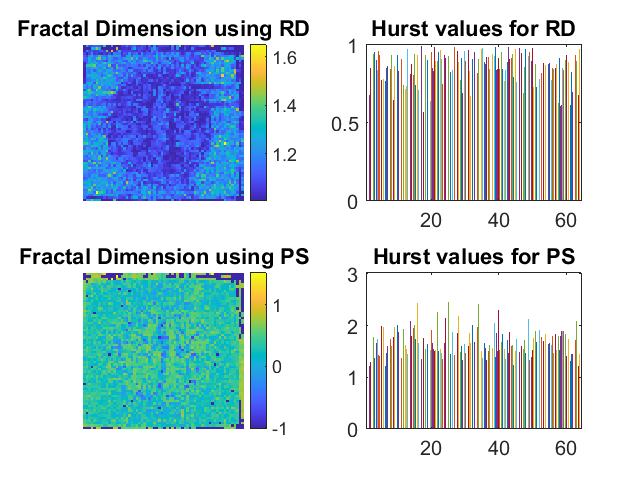

RDfd = zeros(64,64);
hurst_rd = zeros(64, 64);
PSfd = zeros(64,64);
hurst_ps = zeros(64, 64);
diff = (180-128)/2;
new_data = data(:,:, (1+diff):(180-diff));

for y = 1:64
    for x =1:64
        [RDfd(y,x), hurst_rd(y,x)] = fractal_RD(squeeze(new_data(y,x,:))', 1);
        [PSfd(y,x), hurst_ps(y,x)] = fractal_PS(squeeze(new_data(y,x,:) - mean(data(y,x,:)))', 2);
    end
end

figure(14)
subplot(2,2,1)
imagesc(RDfd)
title("Fractal Dimension using RD")
colorbar
axis off

subplot(2,2,2)
bar(hurst_rd)
title("Hurst values for RD")

subplot(2,2,3)
imagesc(PSfd)
title("Fractal Dimension using PS")
colorbar
axis off

subplot(2,2,4)
bar(hurst_ps)
title("Hurst values for PS")

Running the fractal analysis using the power spectral and relative dispersion methods on the data gives the above outputs. The relative dispersion method somewhat pictures the brain although there is a high degree of background noise which interfers with the image. The hurst values are normalized between 0 and 1 with higher values indicating a smoother trend, with less volaity and less roughness, and this data set has many high value hurst values.

The power spectral method is difficult to inspect visually and appears to show minimal areas of significance.with a vague brain shape being possible to identify although that may be due to already knowing the expected pattern. The hurst values show that while there are some values with a very strong positive correlation, there are more values that have a weak correlation. It is also worth nothing that the hurst values are not between 0 and 1 when they are supposed to be so it is difficult to interpret these values since they are incorrect.

Due to the weak correlation it can be said that this data has minimally self similar features. Both of these forms of analysis were not very effective with the power spectral method being less effective than the relative dispersion method.

## Part G: Comparison Of All Methods

As mentionned before both methods of spectral analysis were ineffective due to there being little self similar features within the data with the relative dispersion being more effective than the spectral power analysis. In comparison to the other analysis methods, spectral analysis failed to inform greatly about the brain structure.

Principal component analysis showed that almost all the variance was made up by the first component although interestingly, the second principal component was made up of an outline of the brain possibly due to motion artifacting. The third principal component did slightly feature the same features as the correlation analysis with a reversed directionality. However, other regions of PCA 3 were not reflected in other analysis indicating that these regions may be due to noise. Furthermore, PCA 1 shows signal for regions outside the brain likely due to motion artifacting which requires thresholding similar to the thresholding performed in correlation and fourier analysis. The fourier analysis identified regions within the brain that showed signal change during the activation and deactivation of the block but did not show the directionality. The correlation analysis not only identified the regions within the brain that are correlated to the toggling of the block but also showed the directionality, with the sections on the left side of the image having increased signal when the block was activated and the regions of the right side of the image having increased signal when the block is deactivated. Overall, the most effective analysis were correlation, fourier, PCA, fractal RD, and lastly frastal PS.